# **COMPUTATIONAL FINANCE **

# **WEBINAR II**

# VaR

## When using the Value-at-Risk measure, we are interested in making a statement of the following form:

## "We are X percent certain that we will not lose more than V pounds in time T"

## The variable V is the VaR of the portfolio. It is a function of two parameters: the time horizon T and the confidence level X percent. 

## It is the loss level during a time period of length T that we are X% certain will not be exceeded.

## For example, when T is five days and X=97, VaR is the loss at the 3rd percentile of the distribution of gains over the next five days. 

## Alternatively, it is the loss at the 97th percentile of the distribution of losses over the next five days.  More generally, when the distribution of gains is used, VaR is equal to minus the gain at the (100-X)th percentile of the distribution.

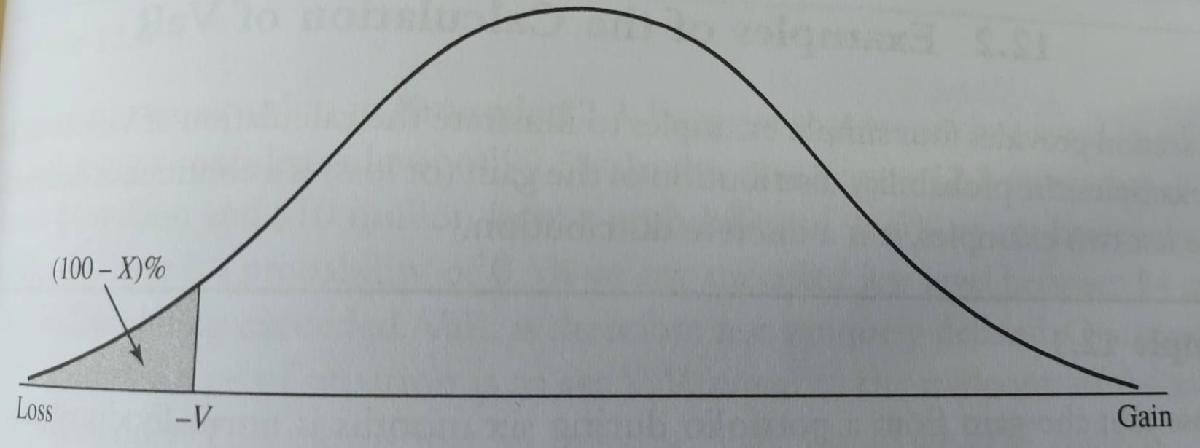

#### Example

#### Suppose that the gain from a portfolio during six months is normally distributed with a mean of £2 m and a standard deviation of £10 m. The 1-percentile point of the normal distribution is

#### 
$$\textsterling 2 m-2.326*\textsterling 10 m = - \textsterling 21.3 m$$


VaR = norminv(0.01,2,10)

VaR = -21.2635

## VaR is an attractive measure, because it is easy to understand. 

## It asks the simple question "How bad can things get?" 

## However, when VaR is used in an attempt to limit the risks taken by a trader, it can lead to undesiderable results. 

## Suppose that a bank tells a trader that the one-day 99% VaR of the trader's portfolio must be limited to £10 m. The trader can contruct a portfolio where there is a 99.1% chance that the daily loss is less then £10 m, and a 0.9% chance that is £500 m. 

## The trader is satysfying the risk limits imposed by the bank, but is clearly taking unacceptable risks. 

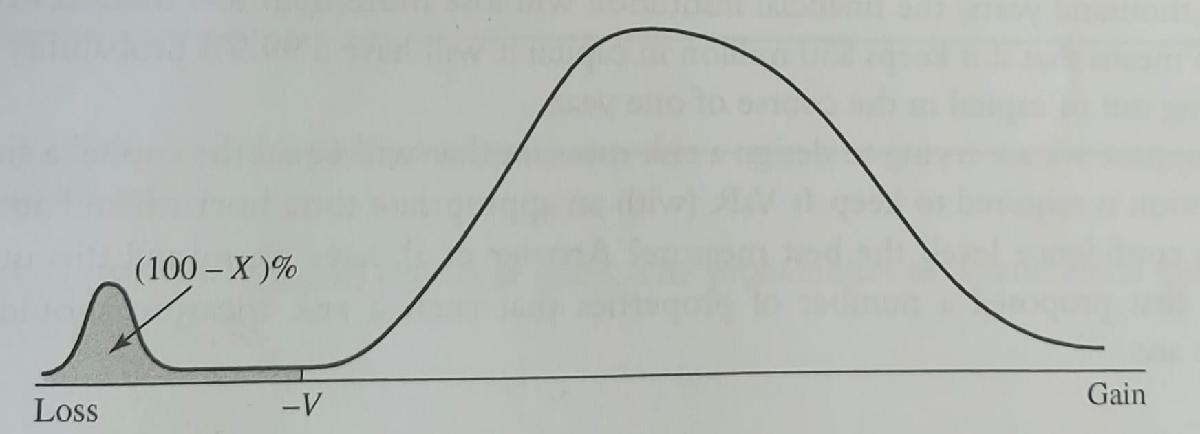

## Even if the two Var for the two distributions are the same, of course the portfolio related to the second distribution is much riskier the the first one.

## It should moreover be noticed that a probability distribution like the one above is not that unusual as one might think.

# Modelling uncertainty

## We assume that a variable, say the price of a stock or a commodity, can be modelled as a random variable, whose probability distribution is known, possibly inferred from available data (we are using only exogeneous uncertainty). 

## The simplest model of uncertainty is the binomial model. 

## We know the current price $S_0$ at time t=0, and we assume that the price $S_1$, at some future time instant t=1, can take only two values.

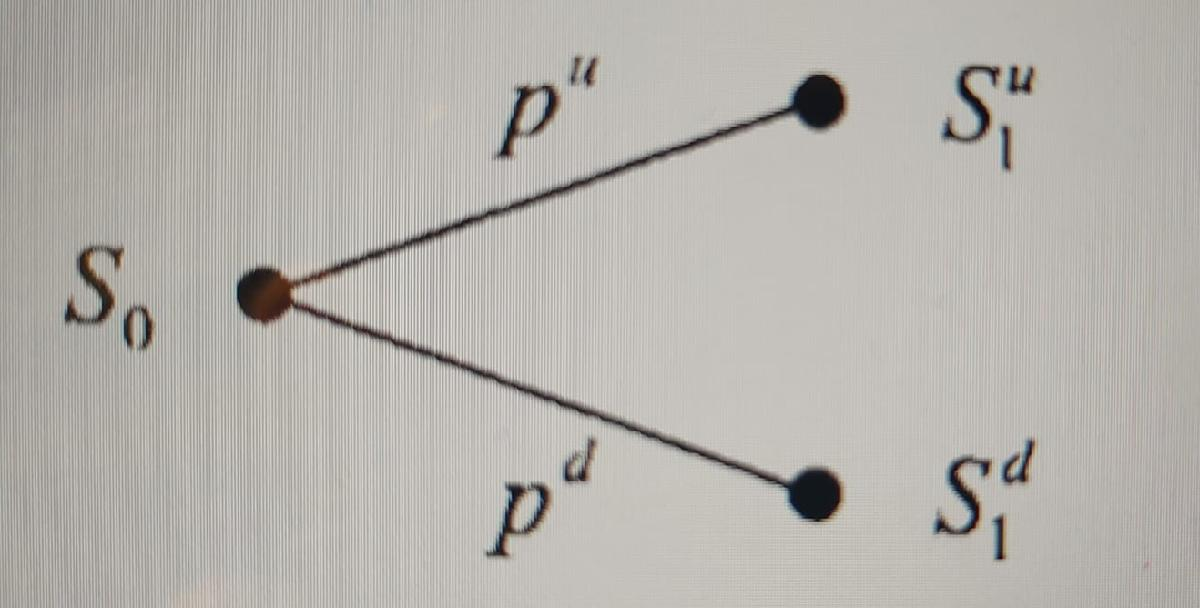

## A common choice is to represent uncertainty by a multiplicative shock, i.e. $S_1^u=uS_0$ and $S_1^d=dS_0$, where the letters u and d suggest 'up' and 'down', respectively (hence, d<u). 

## Apparently, this model is very crude, but it is the building block of very useful models.

## A more refined model can be built by allowing for more then just two future states. 

##  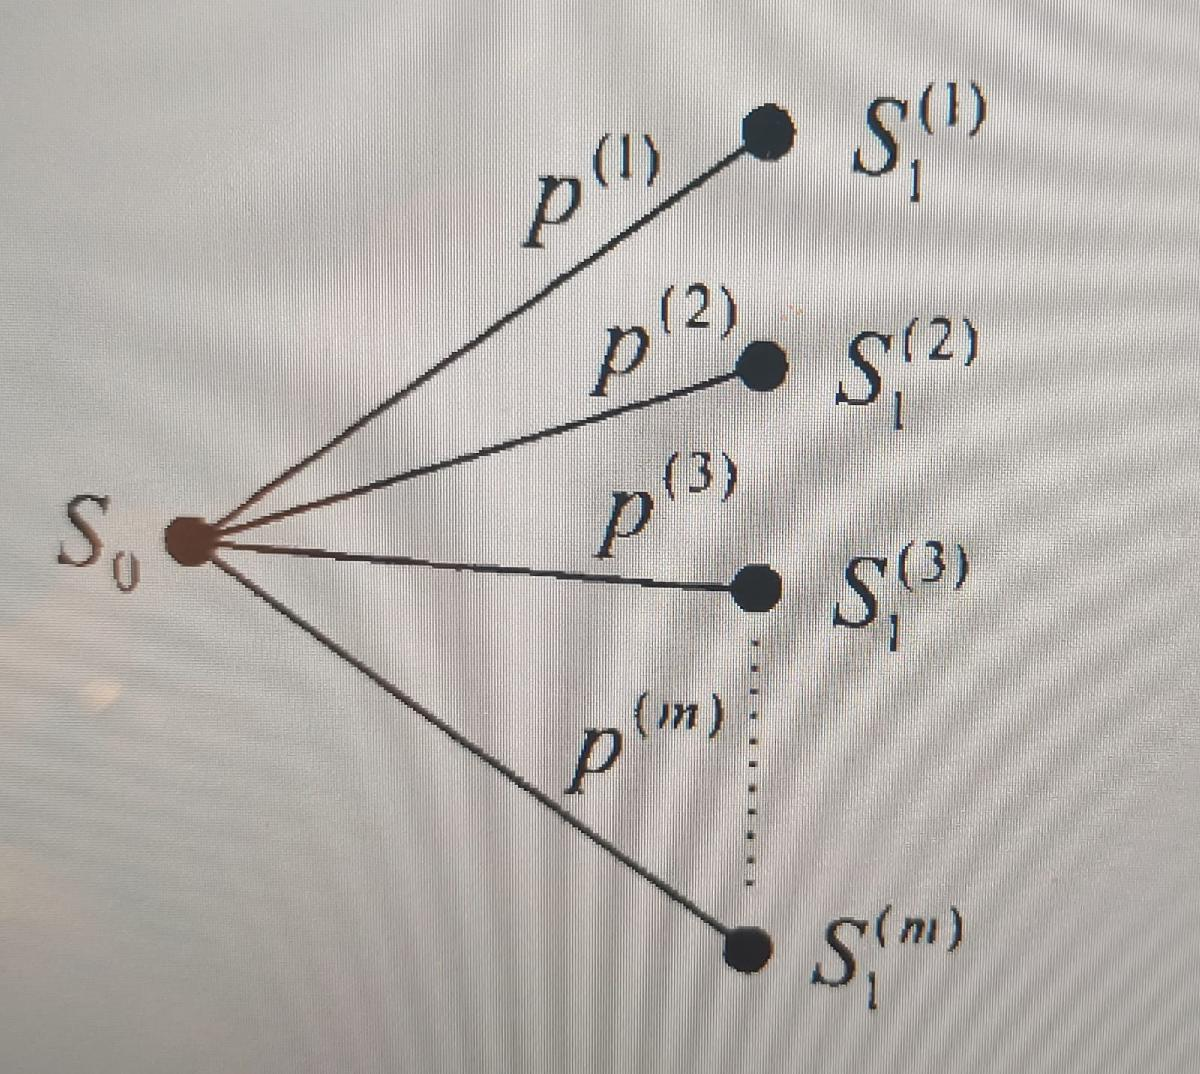

## Moreover, one can consider a discrete-state, discrete-time, multiperiod model

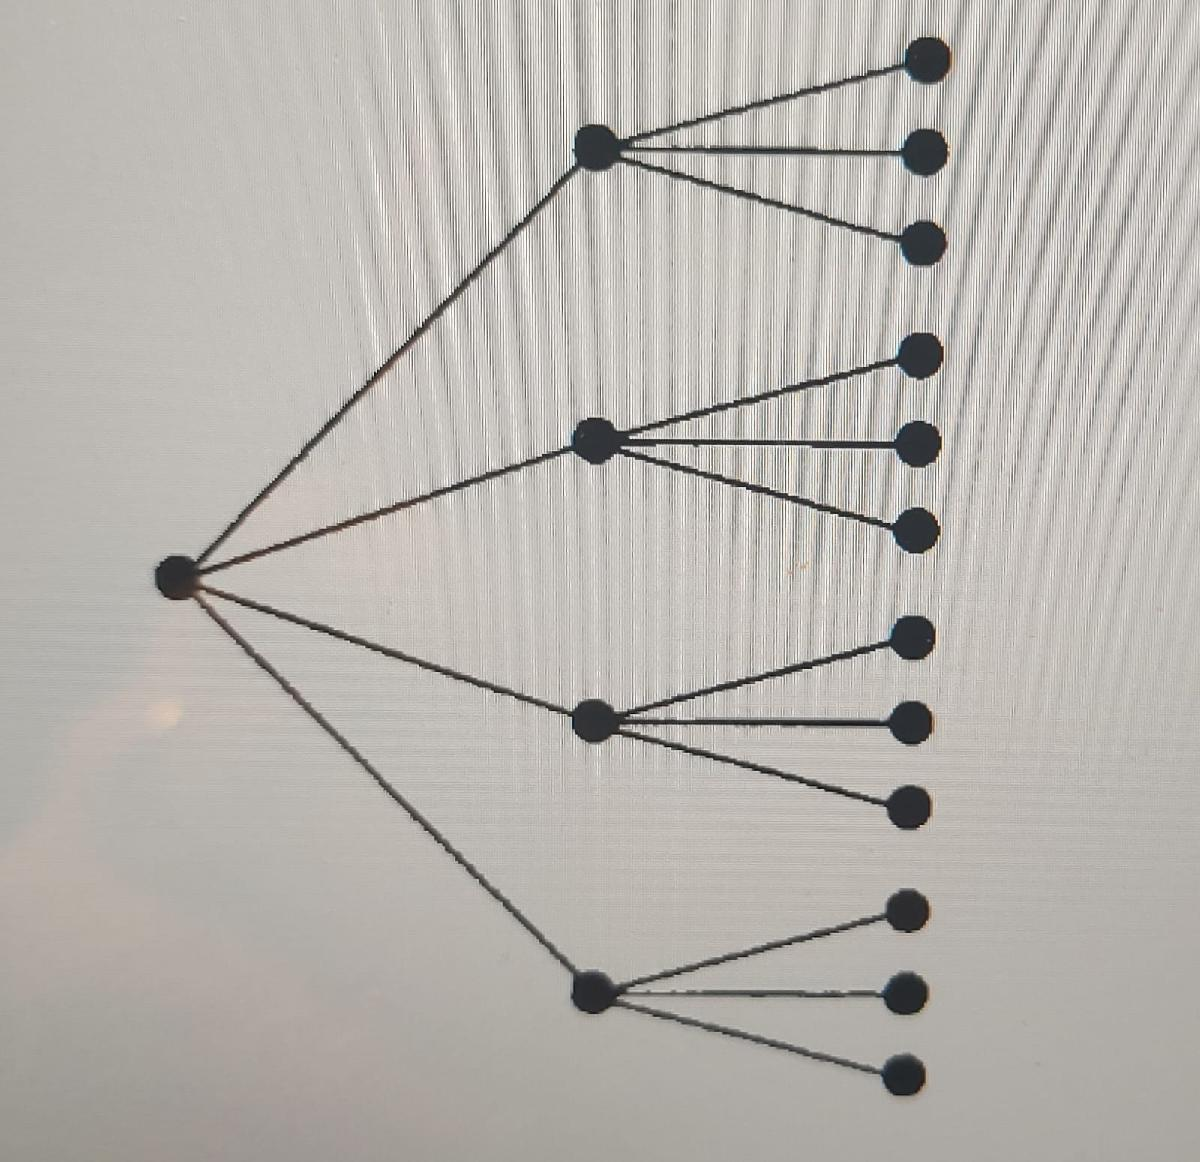

## Sometimes, to keep computational effort limited, we prefer using a recombining lattice.

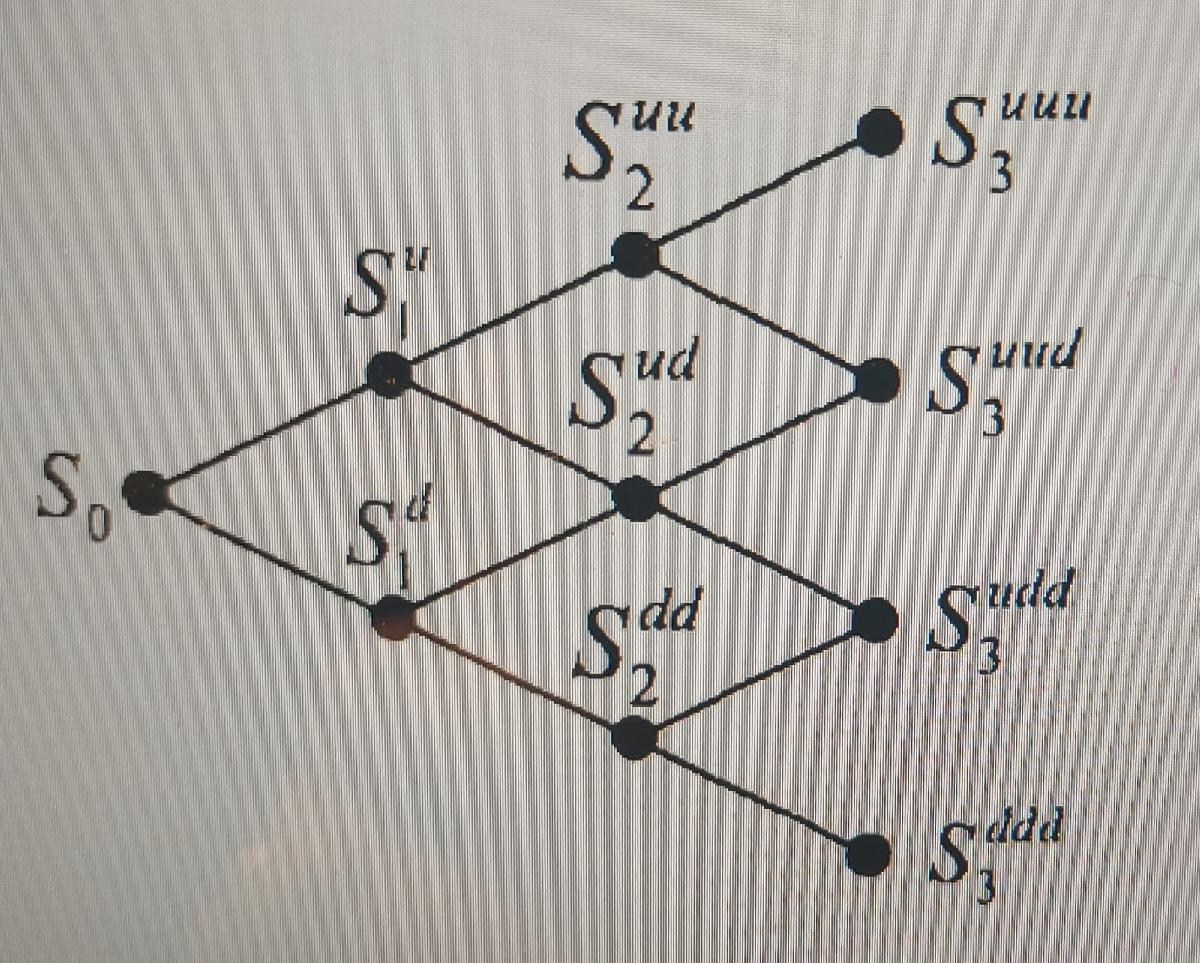

## Since $udS_0=duS_0$, we see that an up-jump followed by a down-jump is the same as a down-jump followed by an up-jump. 

# This means also assuming that the multiplicative shocks are always the same, which makes sense if the process is stationary and time step is constant.

## Sometimes, it is convenient to model uncertainty using instead a continuous distribution, such as the normal. 

## If we think of prices, a continuous distribution is certainly an idealization, since no price is quoted with too many decimal digits. 

## By the same token, we may also resort to continuous-time models, which may be thought of as the limit of a discrete-time model when the time step tends to zero.

## In this case, the usual building block is the Wiener process W(t), that can be considered as the continuous-time limit of a random walk described by a binomial lattice. 

# Geometric Brownian Motion (GBM)

## The standard Wiener process is a useful building block, but it cannot be directly used to model stock prices or interest rates, since (among other issues) it may take negative values. 

## To that aim, we introduce a powerful modelling framework to describe continuous - state, continuous-time processes. Informally, we talk about stochastic differential equations. 

## If we want to write a stochastic differential equation modelling the random return of an asset, we might consider the following modification of the generalized Wiener process:

## 
$$\frac{d S(t)}{S(t)}=\mu dt+\sigma dW(t)$$


## One can think then to that as the differential of log-price, $d\,log\,S_t$ and integrate it directly

## 
$$log\, S(t) -log\,S(0) =\Big( \mu-\frac{\sigma^2}{2}\Big)t+\sigma W(t)$$


## By recalling that $W_t$ has a normal distribution and can be written as $W_t =\epsilon\sqrt t$ with $\epsilon\sim N(0,1)$, we can rewrite the solution in terms of $S_t$ as

# 
$$S(t)=S(0)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)t+\epsilon\sigma\sqrt{t}\Big)$$


## On the one hand, this shows that prices, according to the Geometric Brownian motion model, are log-normally distributed and cannot take negative values.

# On the other hand, now we have a way to generate sample paths, based on a discretization of a prescribed time horizon into time periods of length $\Delta t$.

## A brief note: relation with option pricing. Consider a vanilla option like a European-style call option written on a nondividend paying stock, whose price S(t) follows a geometric Brownian motion. Since increments in the driving Wiener process are independent, we may say that future history does not depend on the past. And we may also show that the value of the option at a time t before maturity will depend only on time (more precisely, time to maturity) and current price of the underlying.

## This leads to the Black-Scholes model (but this is another story...).

# Discretization and Monte Carlo approach

## When discretizing time, you simulate the stock price at time $t+\Delta t$ (tomorrow) by 

# 
$$S(t+\Delta t)=S(t)e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}\Big)$$


## where

## $\mu$ mean return

## $\sigma$standard deviation of returns

## $\epsilon$ random variable


clear all

close all

%% Download full daily history from Stooq
url = "https://stooq.com/q/d/l/?s=spy.us&i=d";
T = readtable(url);

writetable(T,'SPY.xlsx')

rng(123); %set the seed 


T.Date = datetime(T.Date, 'InputFormat','yyyy-MM-dd');
T = sortrows(T, "Date");


T = T(:, {'Date','Close'});
T.Properties.VariableNames{'Close'} = 'AdjClose';

%% Select samples
T_Q4 = T(T.Date >= datetime(2024,10,1) & ...
         T.Date <= datetime(2024,12,31), :);

T_Q1 = T(T.Date >= datetime(2025,1,1) & ...
         T.Date <= datetime(2025,3,31), :);

ans = 64

ans = 60

%% Sanity check
height(T_Q4)
height(T_Q1)

stock_Q4 =   565.0140
  565.2520
  564.2190
  569.3460
  564.1990
  569.5350
  573.4790
  572.4760
  575.9040
  580.6140
  576.1030
  578.6070
  578.6570
  580.8830
  579.9290



stock_Q4 =T_Q4.AdjClose;

stock_Q1 =   582.8870
  590.1750
  593.5750
  586.8650
  587.7230
  578.7490
  579.6470
  580.4440
  591.0030
  589.8660
  595.7880
  601.2420
  604.6220
  607.9220
  606.1470


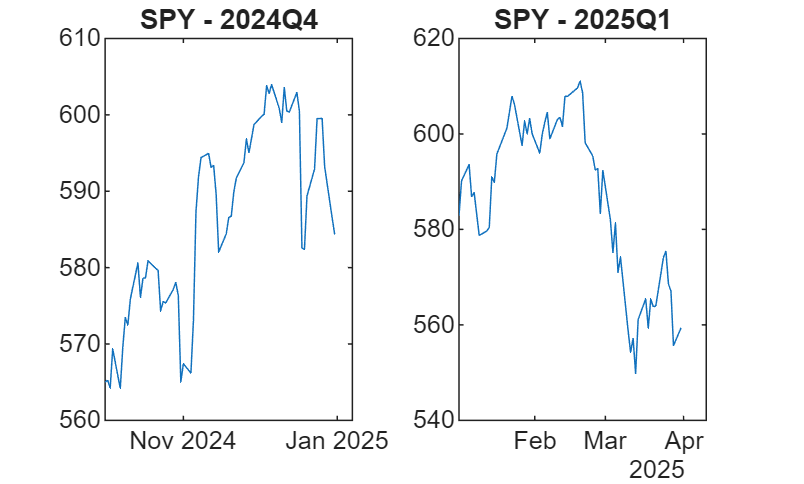


stock_Q1=T_Q1.AdjClose;


subplot(1,2,1)
plot(T_Q4.Date,stock_Q4)
title('SPY - 2024Q4')

subplot(1,2,2)

plot(T_Q1.Date,stock_Q1)
title('SPY - 2025Q1')


#### Q4 2024 reflects political uncertainty without implementation, while Q1 2025 reflects early policy realization (notably trade-related), making a comparison of tail risk economically meaningful.

#### Simulate a bunch of paths  of prices for a month of future trading days based on GBM

## The interval of time is simply one day (with daily frequency)

deltaT = 1;


## extract the value of the recorded last trading day of the stock of interest


S0_Q4 = stock_Q4(end)

S0_Q4 = 584.3230


S0_Q1 = stock_Q1(end)

S0_Q1 = 559.3900

## As a first step you want to calculate the stochastic factors for each of the future intervals of time

# 
$$e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}}$$


## Calculate the random numbers for each interval of time

Setting the parameters for the Monte Carlo simulation

numsim = 1000 %number of simulations

numsim = 1000


sim_days = 20 %set the parameter for how many days I'm projecting in the future

sim_days = 20


epsilon = randn(sim_days,numsim);

epsilon =     0.5377    0.6715   -0.1022   -1.0891    1.4193    0.8404    2.9080    0.0229   -0.2938   -1.3617    0.1832   -1.0642   -1.0667    1.0001    0.9111    0.0799   -1.0149   -1.3981   -0.4677    2.4245    0.2696   -0.4930    0.8123   -0.6407    0.1769   -0.0799   -1.2833    0.8998   -0.4140    0.4136    0.4759    0.9239   -0.9905    2.0243   -0.7578    1.9085    0.4147   -0.5718    0.4207    1.0533    0.5411   -0.4099    1.3845   -1.1223    0.2570    0.4364    1.7985    1.6742   -0.3012   -1.5566
    1.8339   -1.2075   -0.2414    0.0326    0.2916   -0.8880    0.8252   -0.2620   -0.8479    0.4550   -1.0298    1.6035    0.9337   -1.6642    0.5946   -0.9485   -0.4711   -0.2551   -0.1249    0.9594    0.4943   -0.1807    0.5455    1.8089   -0.3075    0.8985   -2.3290   -0.3001   -0.4383   -0.5771    1.4122    0.2669   -1.1730   -2.3595   -0.5640    0.1222    0.3484   -0.2500    0.4007   -0.7489   -1.5409   -0.7113   -0.0627    0.3062   -0.9742   -0.5044   -0.1169    0.1250   -0.698

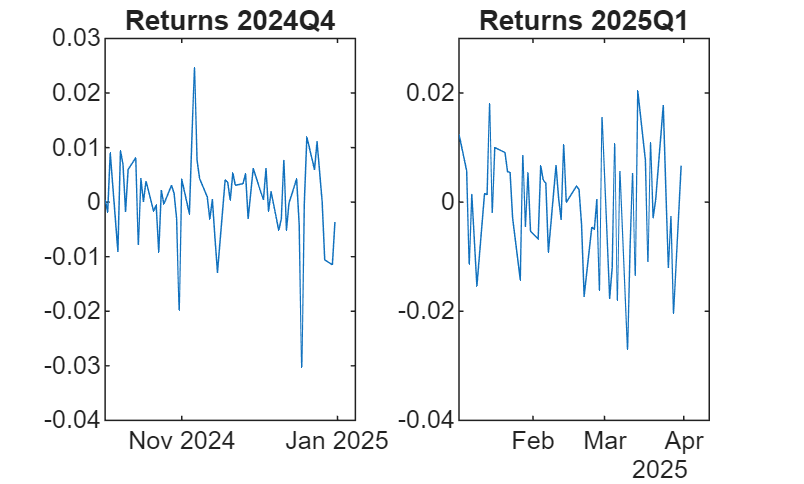


stockReturns_Q1 = diff(log(stock_Q1));

stockReturns_Q4 = diff(log(stock_Q4));

subplot(1,2,1)
plot(T_Q4.Date(2:end),stockReturns_Q4);

title('Returns 2024Q4')

subplot(1,2,2)
plot(T_Q1.Date(2:end),stockReturns_Q1);
ylim([-0.04,0.03])
title('Returns 2025Q1')

#### Calculate the daily log returns and the statistics of interest

# *Which values of* μ *and* σ *make this model best match the observed data?*

##  Diagnostics (before calibrating GBM)

## 1) Stationarity (ADF on log-prices and returns)

## 2) Serial correlation (ACF / Ljung-Box)

## 3) Volatility clustering (ARCH test / ACF of squared returns)

## 4) Distribution (QQ plot / JB test)

## 5) Structural breaks (optional)

## 1)

## We test stationarity on log-prices to confirm the presence of a unit root and justify differencing, and then on log-returns to verify that the transformed series is stationary, as required for GBM calibration.

[h_pricesQ1,p_pricesQ1] = adftest(stockReturns_Q1)

h_pricesQ1 = logical
   1


p_pricesQ1 = 1.0000e-03


[h_pricesQ4,p_pricesQ4] = adftest(stockReturns_Q4)

h_pricesQ4 = logical
   1


p_pricesQ4 = 1.0000e-03

For log prices:

- **Fail to reject** the null hypothesis of a unit root

- Log-prices are **non-stationary**

- Consistent with a **random walk with drift**

- **Differencing is justified**


[h_returnsQ1,p_returnsQ1] = adftest(stockReturns_Q1)

h_returnsQ1 = logical
   1


p_returnsQ1 = 1.0000e-03


[h_returnsQ4,p_returnsQ4] = adftest(stockReturns_Q4)

h_returnsQ4 = logical
   1


p_returnsQ4 = 1.0000e-03

**For log returns:**

- **Reject** the unit root null

- Log-returns are **stationary**

- Mean and variance are stable over time

-  Calibration of a single μ and σ is statistically meaningful

## 2)

## We test for serial correlation to check whether **returns are independent over time**, as required by the GBM and by the way we simulate future paths.

h_Q1 = lbqtest(stockReturns_Q1)  %by default 20 lags are included

h_Q1 = logical
   0



h_Q4 = lbqtest(stockReturns_Q1)

h_Q4 = logical
   0


The Ljung–Box test fails to reject the null of no serial correlation in returns, supporting the assumption of independent innovations required by the GBM and Monte Carlo simulation.

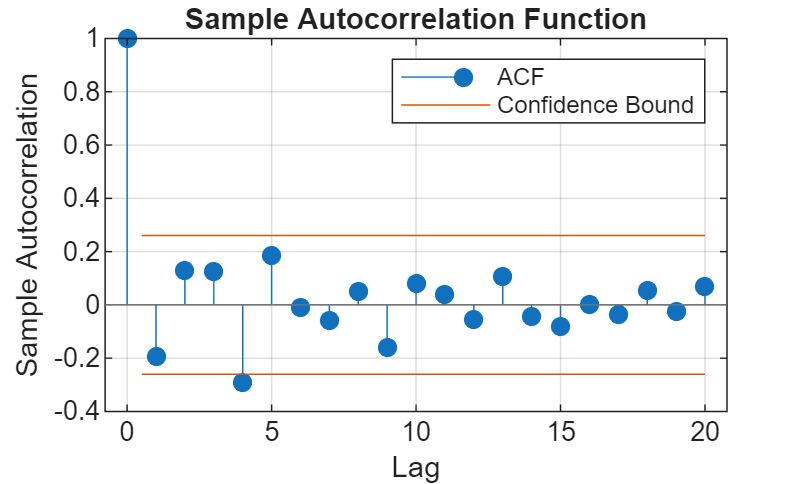

autocorr(stockReturns_Q1)

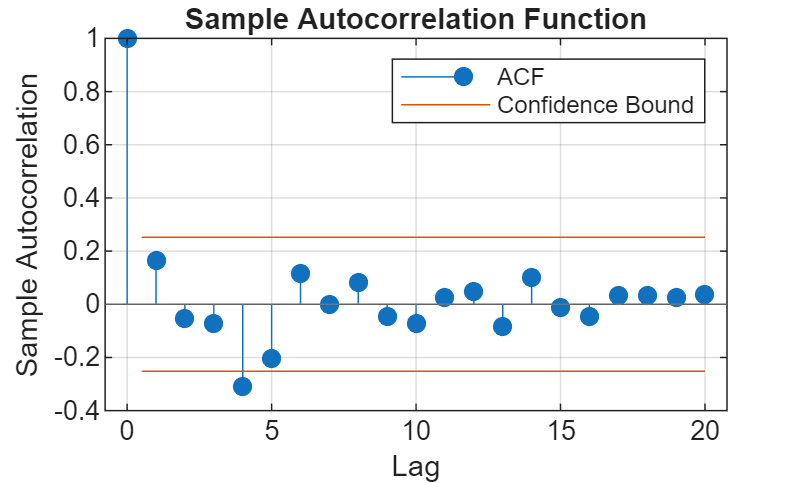


autocorr(stockReturns_Q4)

## 3)

## We test for volatility clustering to verify whether a *single, constant* σ is a valid description of risk over time.

h = archtest(stockReturns_Q1)

h = logical
   0



h = archtest(stockReturns_Q4)

h = logical
   0


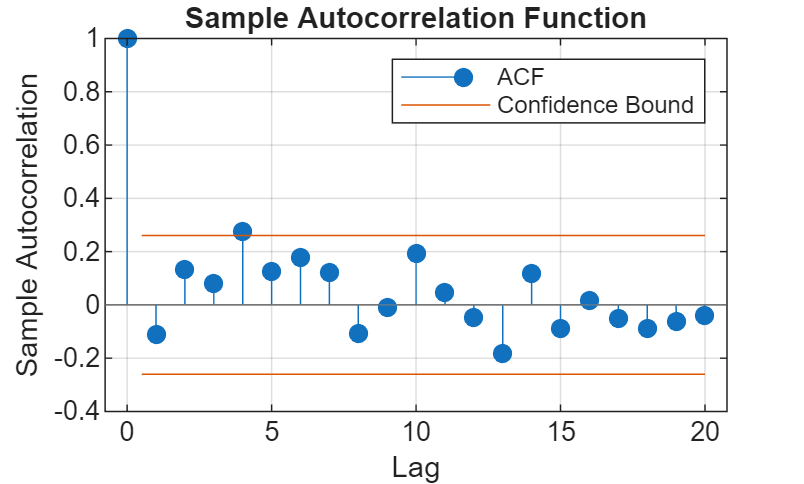


autocorr(stockReturns_Q1.^2)

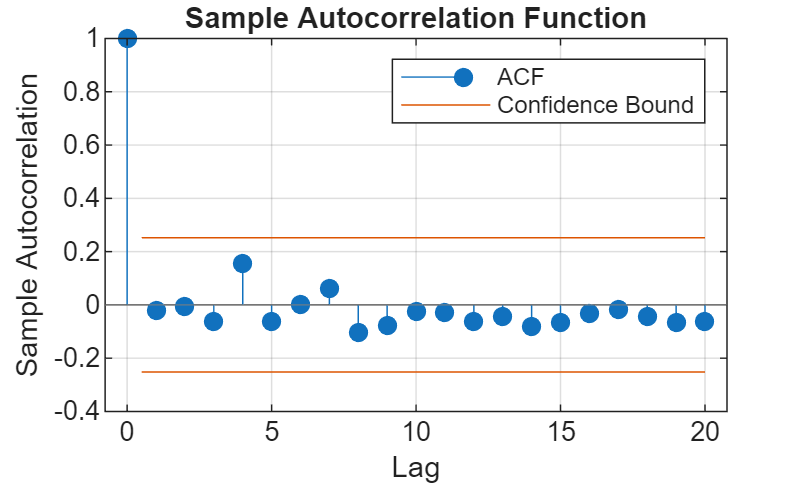


autocorr(stockReturns_Q4.^2)

The ARCH test fails to reject the null of no conditional heteroskedasticity in both samples, so we do not find statistical evidence of volatility clustering; therefore a constant-volatility GBM is a reasonable simplifying assumption for this exercise.

## 4)

## QQ plots and the JB test are primarily used to detect **departures from normality**, and in financial returns this typically manifests as **fat tails**, which imply that normal-based GBM VaR may underestimate extreme losses.

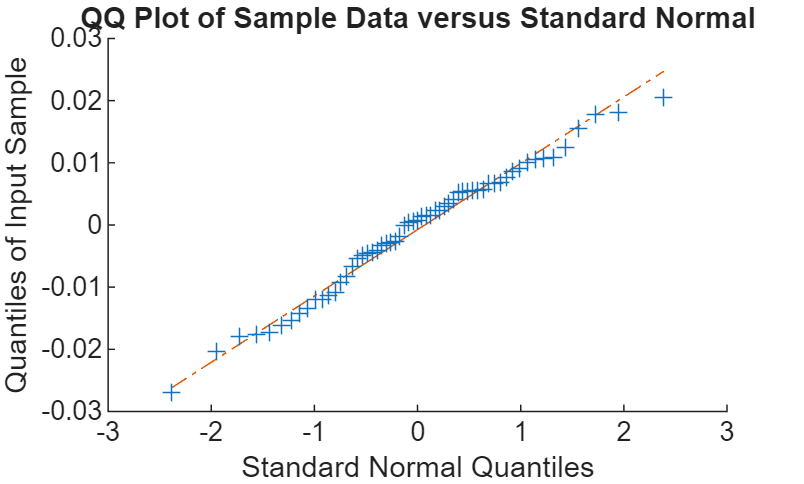


qqplot(stockReturns_Q1)  

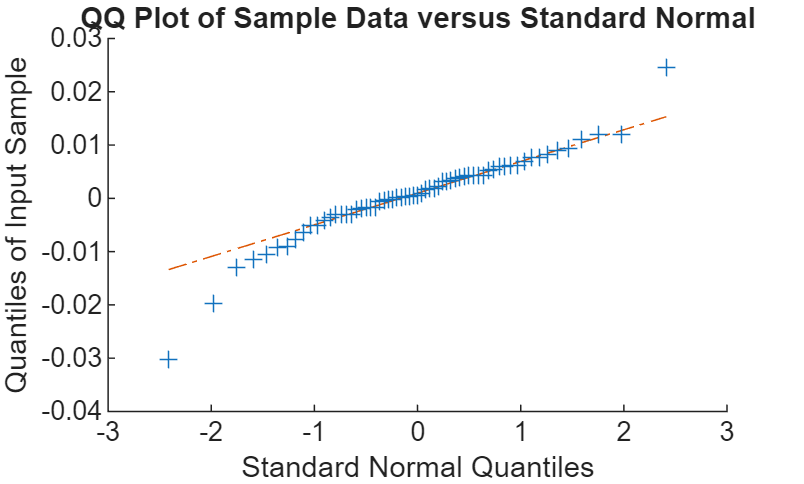

qqplot(stockReturns_Q4)  %QQ plot against the normal distribution



% Jarque–Bera normality test
jbtest(stockReturns_Q1)

ans = 0


jbtest(stockReturns_Q4)

ans = 1

The QQ plot for Q1 2025 shows mild deviations in the tails, suggesting weak fat-tail behavior, while the Gaussian approximation remains reasonable for most observations.

The QQ plot for Q4 2024 exhibits stronger tail deviations, particularly in the lower tail, indicating heavier tails and potential downside risk relative to the normal distribution.

Normality appears to be a better approximation in Q1 2025 than in Q4 2024, although tail deviations are present in both samples.

The QQ plots indicate that returns are approximately normally distributed in the central region, but exhibit deviations in the tails, particularly in Q4 2024 where downside tail risk appears more pronounced. This suggests the presence of mild fat-tail behavior, implying that normal-based GBM VaR may underestimate extreme losses, especially at high confidence levels.

Consistently, the Jarque–Bera test rejects normality for Q4 2024 but fails to reject it for Q1 2025, suggesting that fat tails are statistically relevant in the former period but less so in the latter.

#### 5)

#### Structural break tests are performed when there is economic or visual evidence that the parameters of the return process may have changed; in their absence, a single-regime model is preferred for parsimony (optional).




mu_Q4 = mean(stockReturns_Q4)

mu_Q4 = 5.3339e-04


mu_Q1 = mean(stockReturns_Q1)

mu_Q1 = -6.9740e-04


sigma_Q4 = std(stockReturns_Q4)

sigma_Q4 = 0.0079


sigma_Q1 = std(stockReturns_Q1)

sigma_Q1 = 0.0104

## Evaluate the stochastic factors

# 
$$e^{\Big(\mu-\frac{\sigma^2}{2}\Big)\Delta t+\epsilon\sigma\sqrt{\Delta t}}$$





factor_Q4 = exp((mu_Q4-sigma_Q4^2/2)*deltaT + sigma_Q4*epsilon*sqrt(deltaT));

factor_Q1 = exp((mu_Q1-sigma_Q1^2/2)*deltaT + sigma_Q1*epsilon*sqrt(deltaT));

## Now, you can multiply each factor by the stock price of the given day (starting from the last trading day) to create the path (a realization of the stochastic process).

## Concatenate vertically the last price to the vector of stochastic factors


S0_Q4*ones(1,numsim;

ans =   584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230




factor_Q4 = [S0_Q4*ones(1,numsim);factor_Q4];

factor_Q4 =   584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230  584.3230
    1.0048    1.0058    0.9997    0.9919    1.0118    1.0072    1.0238    1.0007    0.9982    0.9898    1.0020    0.9921    0.9921    1.0085    1.0077    1.0011    0.9925    0.9895    0.9968    1.0199    1.0026    0.9966    1.0070    0.9954    1.0019    0.9999    0.9904    1.0077    0.9972    1.0038    1.0043    1.0079    0.9927    1.0167    0.9945    1.0157    1.0038    0.9960    1.0038    1.0089    1.0048    0.9973    1.0115    0.9916    1.0025    1.0040    1.0149    1.0139    0.9


factor_Q1 = [S0_Q1*ones(1,numsim);factor_Q1];

factor_Q1 =   559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900  559.3900
    1.0049    1.0063    0.9982    0.9880    1.0141    1.0080    1.0300    0.9995    0.9962    0.9852    1.0012    0.9882    0.9882    1.0097    1.0088    1.0001    0.9887    0.9848    0.9944    1.0248    1.0021    0.9941    1.0077    0.9926    1.0011    0.9984    0.9860    1.0087    0.9950    1.0036    1.0042    1.0089    0.9890    1.0205    0.9914    1.0193    1.0036    0.9933    1.0036    1.0103    1.0049    0.9950    1.0138    0.9876    1.0019    1.0038    1.0181    1.0168    0.9

## calculate the cumulative product using the vector of factors which was concatenated with the value of the last trading day


path_Q4 = cumprod(factor_Q4);

path_Q1 = cumprod(factor_Q1);


## Now I have simulated the closing prices of the stock for the chosen number of future days after the last recorded price

## The path is stored as a colum vector that can be plotted.

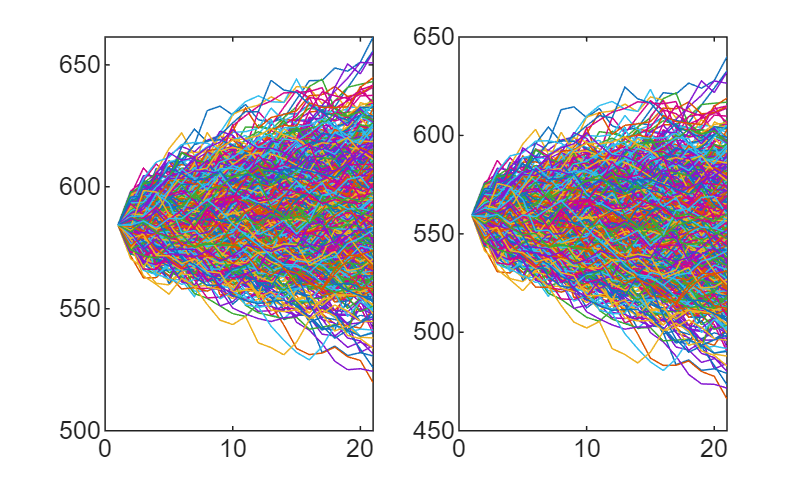

subplot(1,2,1)
plot(path_Q4)

subplot(1,2,2)
plot(path_Q1)

## Plot the path along with the historical prices in a different graphic window

## Evaluate VaR of simulated prices

#### Extract the simulated final prices

finalPrices_Q4 = path_Q4(end,:);

finalPrices_Q1 = path_Q1(end,:);

Calculate the log returns of each path over the simulated days by subtracting the log of the initial price (S0) from the log of the final prices. 

Store the returns vector

 

possibleReturns_Q4 = log(finalPrices_Q4)-log(S0_Q4);

possibleReturns_Q1 = log(finalPrices_Q1)-log(S0_Q1);


plot the histogram of returns with a given number of bins

subplot(1,2,1)
histogram(possibleReturns_Q4,20)


 Calculate the 5% VaR, i.e. the fifth percentile of the possible returns (the function prctile(v,p) calculate the p percentile of the values in the vector v

 
var5_Q4 = -prctile(possibleReturns_Q4,1)


hold on


visualize VaR by plotting a red colored line representing 5 percent Value at Risk on top of the histogram


plot([-var5_Q4 -var5_Q4],[0 150],'r')

var5_Q4 = 0.0789

title('Simulated Returns—2024Q4')
hold off


subplot(1,2,2)
histogram(possibleReturns_Q1,20)


 Calculate the 5% VaR, i.e. the fifth percentile of the possible returns (the function prctile(v,p) calculate the p percentile of the values in the vector v

 
var5_Q1 = -prctile(possibleReturns_Q1,1)


hold on


visualize VaR by plotting a red colored line representing 5 percent Value at Risk on top of the histogram


plot([-var5_Q1 -var5_Q1],[0 150],'r')

var5_Q1 = 0.1319

title('Simulated Returns—2025Q1')
hold off

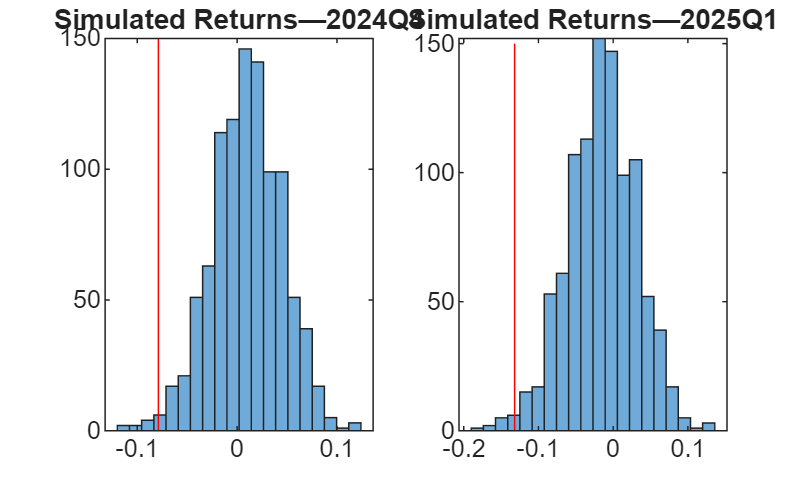



% --- Convert return-VaR (log) to monetary VaR (per 1 share) ---
VaR_money_Q4 = S0_Q4 * (1 - exp(-var5_Q4))   % dollars (or same currency as S0), per share

VaR_money_Q1 = S0_Q1 * (1 - exp(-var5_Q1))


V0=1000 %as an example

VaR_money_Q4 = V0 * (1 - exp(-var5_Q4))

VaR_money_Q1 = V0 * (1 - exp(-var5_Q1))

VaR_money_Q4 = 44.3287

VaR_money_Q1 = 69.1410

## Interesting additional references:

## [1] Glasserman, P. Monte Carlo Methods in Financial Engineering. Springer-Verlag, New York, 2004.

## [2] Hull, J. C. Options, Futures, and Other Derivatives. 5th edition, Englewood Cliffs, NJ: Prentice Hall, 2002

function stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)

V0 = 1000

% fetchYahooFinanceData Fetches historical stock data from Yahoo Finance.
%

VaR_money_Q4 = 75.8634

%   stockData = fetchYahooFinanceData(symbol, startDate, endDate, interval, fields)
%

VaR_money_Q1 = 123.6008

%   Parameters:

s = struct with fields:
     Type: 'twister'
     Seed: 0
    State: [625×1 uint32]


%       symbol     - Stock symbol as a string (e.g., 'AAPL').
%       startDate  - Start date as a string or datetime ('dd-mmm-yyyy' format).
%       endDate    - End date as a string or datetime ('dd-mmm-yyyy' format).
%       interval   - Data interval: '1d' (daily), '1wk' (weekly), '1mo' (monthly).
%       fields     - Cell array of strings -i.e.curly brackets needed to
%       enter input, specifying data fields to retrieve, one or more
%                    Valid fields: 'open', 'close', 'high', 'low',
%                    'volume'. e.g.{'open', 'high', 'low', 'close', 'volume'}, 
%
%   Returns:
%       stockData  - Table containing the date and requested data fields.

    % Validate inputs
    if nargin < 5
        error('All five arguments (symbol, startDate, endDate, interval, fields) are required.');
    end

    % Convert dates to datetime if necessary
    if ischar(startDate) || isstring(startDate)
        startDate = datetime(startDate, 'InputFormat', 'dd-MMM-yyyy');
    end
    if ischar(endDate) || isstring(endDate)
        endDate = datetime(endDate, 'InputFormat', 'dd-MMM-yyyy');
    end

    % Validate interval
    validIntervals = {'1d', '1wk', '1mo'};
    if ~ismember(interval, validIntervals)
        error('Invalid interval. Choose from ''1d'', ''1wk'', or ''1mo''.');
    end

    % Convert dates to UNIX timestamps
    startNum = posixtime(datetime(startDate));
    endNum = posixtime(datetime(endDate));

    % Construct the URL
    url = ['https://query1.finance.yahoo.com/v8/finance/chart/' symbol ...
           '?period1=' num2str(floor(startNum)) '&period2=' num2str(floor(endNum)) '&interval=' interval];

    % Set web options with a user-agent header to mimic a browser
    options = weboptions('ContentType', 'json', 'UserAgent', 'Mozilla/5.0');

    % Fetch data
    try
        data = webread(url, options);
    catch ME
        error('Failed to retrieve data: %s', ME.message);
    end

    % Check for errors in response
    if isempty(data.chart.result) || ~isempty(data.chart.error)
        error('Failed to retrieve data. Please check the stock symbol and date range.');
    end

    % Extract the result
    result = data.chart.result;
    if iscell(result)
        result = result{1};
    elseif isstruct(result) && numel(result) > 1
        result = result(1);
    end

    % Extract timestamps
    if isfield(result, 'timestamp')
        timestamps = result.timestamp;
    else
        error('No timestamp data available.');
    end

    % Convert timestamps to datetime
    dates = datetime(timestamps, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');

    % Access indicators
    if isfield(result, 'indicators') && isfield(result.indicators, 'quote')
        quote = result.indicators.quote;
        if iscell(quote)
            quote = quote{1};
        elseif isstruct(quote) && numel(quote) > 1
            quote = quote(1);
        end
    else
        error('No quote data available.');
    end

    % Initialize table with dates
    stockData = table(dates, 'VariableNames', {'Date'});

    % Ensure fields are in lowercase
    fields = lower(fields);

    % Valid fields in the data
    validFields = fieldnames(quote);

    % For each requested field, extract the data
    for i = 1:length(fields)
        field = fields{i};
        if ismember(field, validFields)
            fieldData = quote.(field);
            fieldData = fieldData(:);  % Ensure column vector
            % Handle missing data
            if length(fieldData) < length(dates)
                fieldData(end+1:length(dates)) = NaN;
            elseif length(fieldData) > length(dates)
                fieldData = fieldData(1:length(dates));
            end
            % Append to table with capitalized field name
            stockData.(capitalizeFirstLetter(field)) = fieldData;
        else
            warning('Field "%s" is not available in the data.', field);
            % Fill with NaNs if field is missing
            stockData.(capitalizeFirstLetter(field)) = NaN(height(stockData), 1);
        end
    end

    % Remove rows where all data fields are NaN
    dataFields = stockData.Properties.VariableNames(2:end);
    validRows = any(~isnan(stockData{:, dataFields}), 2);
    stockData = stockData(validRows, :);

    % Reset the datetime to remove time zone information
    stockData.Date.TimeZone = '';

end

function outStr = capitalizeFirstLetter(inStr)
% Helper function to capitalize the first letter of a string
    outStr = lower(inStr);
    if ~isempty(outStr)
        outStr(1) = upper(outStr(1));
    end
end

